Code for this was obtained and modified from [MATLAB user Torsten's post](https://www.mathworks.com/matlabcentral/answers/430248-how-do-i-plot-a-1-d-random-walk-that-generate-1-and-1-with-equal-probability-i-am-struggling-to-pl). 

Sampling from user-defined distribution: [Adam Nieslony code](https://www.mathworks.com/matlabcentral/fileexchange/26003-random-numbers-from-a-user-defined-distribution)

## **1D Random Walk **

Simulating polymer movement. 

close all;
clear all; 

% Constants
kB = 1.38*10^(-23);             % Boltzmann constant [J/K]

% Setup and conditions 
F = 5*10^(-21);                 % Applied force [Newtons], scaled for micro purposes 
T = 298;                        % Temperature [K]

% Chain setup
L = 1;                          % Length of link [m]
n = 20;                         % Number of units 
P = zeros(n,1);
P(1) = 0;                       % Starting value

% Calculating probabilities of moving left and right 
A = 1/(2*cosh(F*L/(kB*T)));    % Normalization factor
p_left = A*exp(-F*L/(kB*T));
p_right = A*exp(F*L/(kB*T));

disp("P_left: " + num2str(p_left));

P_left: 0.080789


disp("P_right: " + num2str(p_right));

P_right: 0.91921


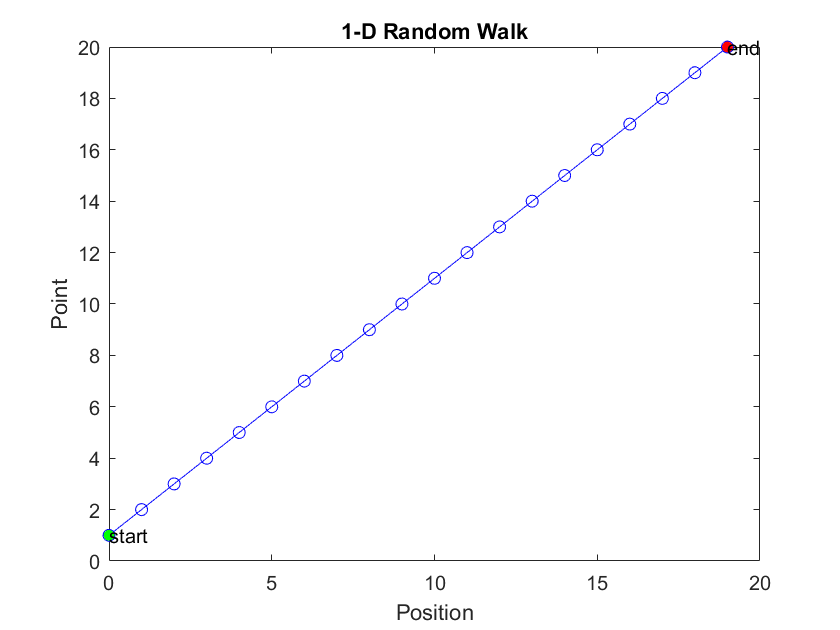


% Performing random walk 
for i=2:n    % i is the number of steps from 1 to 10
    R = rand;
    S = 0; 
    
    if R < p_left
        S = -1;
    else
        S = 1;
    end
    
    P(i) = S+P(i-1); % Gives the next random walk from the new position P every time
end

% Creating a plot 
plot(P, [1:n], 'bo-');
title('1-D Random Walk');
xlabel('Position');
ylabel('Point');

% Mark the first point in red.
hold on;
plot(P(1), 1, 'go',...
    'MarkerFaceColor', 'g',...
    'MarkerSize', 5);
text(P(1), 1, 'start');

% Mark the end point in red.
hold on;
plot(P(n), n, 'ro',...
    'MarkerFaceColor', 'r',...
    'MarkerSize', 5);
text(P(n), n, 'end');

## **2D Random Walk **

close all;
clear all; 

% Constants
kB = 1.38*10^(-23);             % Boltzmann constant [J/K]

% Setup and conditions 
F = 1*10^(-21);                 % Applied force [Newtons], scaled for micro purposes 
T = 298;                        % Temperature [K]

% Chain setup
L = 1;                          % Length of link [m]
n = 10;                         % Number of units 
P = zeros(2,n);
P(:,1) = 0;                     % Starting value

We begin the simulations starting with idea of cardinal movements (left, right, up, and down). We are assuming that the two axes are independent of each other, and that the particle can move either left or right AND up or down. 

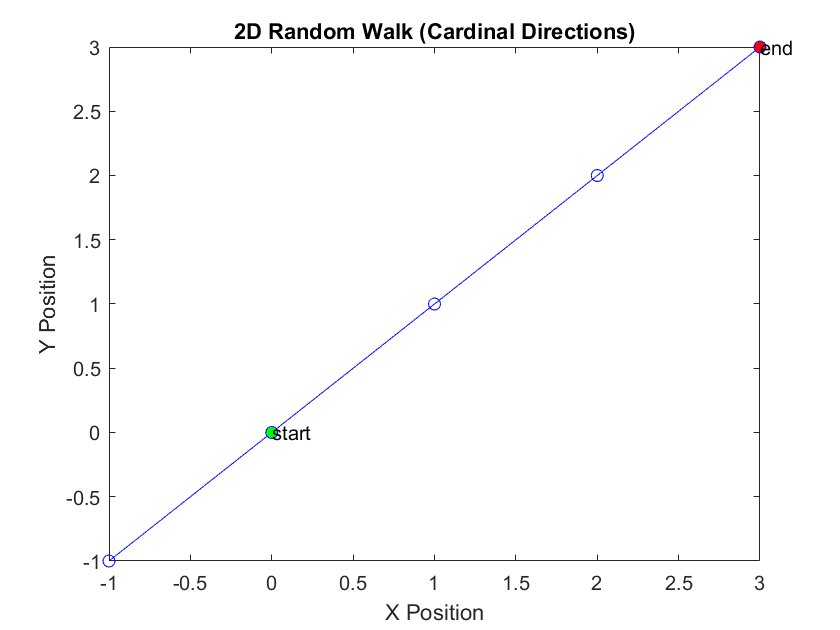

% Calculating probabilities of moving right and left  
A = 1/(2*cosh(F*L/(kB*T)));    % Normalization factor
p_left = A*exp(-F*L/(kB*T));
p_right = A*exp(F*L/(kB*T));

% Calculating probabilities of moving up and down 
A = 1/(2*cosh(F*L/(kB*T)));    % Normalization factor
p_down = A*exp(-F*L/(kB*T));
p_up = A*exp(F*L/(kB*T));

%% Performing 2D random walk 
% Steps are size 1, goes in cardinal directions
for i=2:n    % i is the number of steps from 1 to 10
    
    dx = rand; 
    if dx < p_left
        dx = -1;
    else
        dx = 1;
    end
    
    dy = rand; 
    if dx < p_down
        dy = -1;
    else
        dy = 1;
    end
    
    P(:,i) = [dx, dy]' + P(:,i-1); % Gives the next random walk from the new position P every time
end


% Creating a plot 
plot(P(1,:), P(2,:), 'bo-');
title('2D Random Walk (Cardinal Directions)');
xlabel('X Position');
ylabel('Y Position');

% Mark the first point in red.
hold on;
plot(P(1,1), P(2,1), 'go',...
    'MarkerFaceColor', 'g',...
    'MarkerSize', 5);
text(P(1,1), P(2,1), 'start');

% Mark the end point in red.
hold on;
plot(P(1,n), P(2,n), 'ro',...
    'MarkerFaceColor', 'r',...
    'MarkerSize', 5);
text(P(1,n), P(2,n), 'end');

Now we try to do the same but with the proper distribution.

[https://www.mathworks.com/help/stats/makedist.html](https://www.mathworks.com/help/stats/makedist.html) 

[https://www.mathworks.com/help/stats/prob.exponentialdistribution.html](https://www.mathworks.com/help/stats/prob.exponentialdistribution.html) 

[https://www.mathworks.com/matlabcentral/answers/453447-how-do-i-generate-a-random-number-with-normal-distribution](https://www.mathworks.com/matlabcentral/answers/453447-how-do-i-generate-a-random-number-with-normal-distribution) 

[https://www.mathworks.com/help/stats/exprnd.html#mw_5523c4b3-8a56-4f8c-bb1c-9129584e837c](https://www.mathworks.com/help/stats/exprnd.html#mw_5523c4b3-8a56-4f8c-bb1c-9129584e837c) 

close all;
clear all; 

% Constants
kB = 1.38;             % Boltzmann constant [J/K]

% Setup and conditions 
Fx = 0;                % Applied force [Newtons], scaled for micro purposes 
Fy = 0; 
T = 298;                        % Temperature [K]

% Chain setup
L = 1;                          % Length of link [m]
n = 10;                         % Number of units 
P = zeros(2,n);
P(:,1) = 0;                     % Starting value

Here, we will draw a random theta value from the Boltzmann distribution. In order to sample randomly, we will need to first generate the CDF of the Boltzmann. Next, we will then take the inverse of the CDF to sample a value from that given a uniformly generated random value from 0 to 1. 

% Solving for normalization constant 
Boltzmann_dist = @(theta) exp((L*cos(theta)*Fx + L*sin(theta)*Fy)/(kB*T));
Normalization_const = 1/integral(Boltzmann_dist, 0, 2*pi);

% Creating distribution to sample from 
theta_vals = linspace(0, 2*pi, 100);
CDF = zeros(size(theta_vals));
for i = 1:length(theta_vals)
    CDF(i) = Normalization_const*integral(Boltzmann_dist, 0, theta_vals(i));
end

Now that we have the distribution set up, we draw a random theta value to sample from our distribution: 

% Performing 2D random walk 
for i=2:n    % i is the number of steps from 1 to 10
    
    rand_val = rand; 
    theta = interp1(CDF, theta_vals, rand_val);
    
    dx = L*cos(theta);
    dy = L*sin(theta); 
    
    P(:,i) = [dx, dy]' + P(:,i-1); % Gives the next random walk from the new position P every time
end

Now we create our plots as usual. 

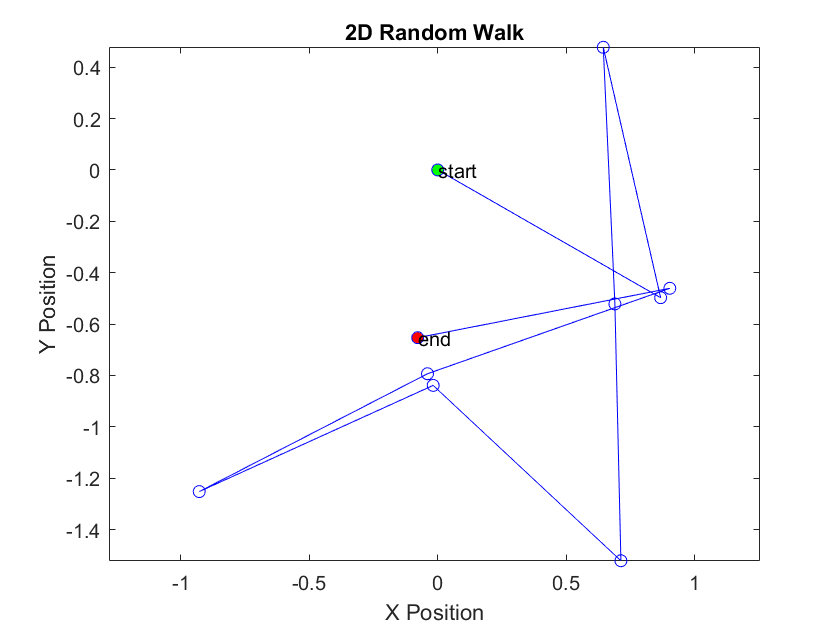

% Creating a plot 
plot(P(1,:), P(2,:), 'bo-');
title('2D Random Walk');
xlabel('X Position');
ylabel('Y Position');

% Keep the tick sizes the same 
axis equal; 

% Mark the first point in red.
hold on;
plot(P(1,1), P(2,1), 'go',...
    'MarkerFaceColor', 'g',...
    'MarkerSize', 5);
text(P(1,1), P(2,1), 'start');

% Mark the end point in red.
hold on;
plot(P(1,n), P(2,n), 'ro',...
    'MarkerFaceColor', 'r',...
    'MarkerSize', 5);
text(P(1,n), P(2,n), 'end');

### 3D Random Walk

close all;
clear all; 

% Constants
kB = 1.38*10^(-23);             % Boltzmann constant [J/K]

% Setup and conditions 
Fx = 0;                % Applied force [Newtons], scaled for micro purposes 
Fy = 0; 
Fz = 5*10^(-21); 
F = [Fx, Fy, Fz]';
T = 298;                        % Temperature [K]

% Chain setup
L = 1;                          % Length of link [m]
n = 10;                         % Number of units 
P = zeros(3,n);
P(:,1) = 0;                     % Starting value

Uniform distribution on sphere: [https://www.bogotobogo.com/Algorithms/uniform_distribution_sphere.php](https://www.bogotobogo.com/Algorithms/uniform_distribution_sphere.php)

num_values = 500; 
theta = linspace(0, 2*pi, num_values);
phi = linspace(0, pi, num_values);
[THETA,PHI] = meshgrid(theta, phi);

% p(theta, phi)
BOLTZMANN_2D = exp(...
            (L*sin(PHI).*cos(THETA)*Fx + L*sin(PHI).*sin(THETA)*Fy + L*cos(PHI)*Fz)/(kB*T));
BOLTZMANN_2D = BOLTZMANN_2D / sum(BOLTZMANN_2D(:));

THETA_PDF = sum(BOLTZMANN_2D, 1);   % P(theta)
THETA_CDF = [0 cumsum(THETA_PDF)];  % CDF(P(theta))

This is where we sample points

% Performing 3D random walk 
for i=2:n    
    
    rand_theta = rand;
    rand_phi = rand;
    
    sampled_theta = interp1(THETA_CDF, [0 theta], rand_theta);
    
    % Sample from the marginal dist p(phi | theta)
    sampled_phi = interp1([0; phi_cdf(sampled_theta, THETA, PHI, BOLTZMANN_2D, num_values, phi)], [0 phi], rand_phi);
    
    dx = L.*sin(sampled_phi).*cos(sampled_theta);
    dy = L.*sin(sampled_phi).*sin(sampled_theta);
    dz = L.*cos(sampled_phi);
    
    P(:,i) = [dx, dy, dz]' + P(:,i-1); % Gives the next random walk from the new position P every time
end

Finally we plot. 

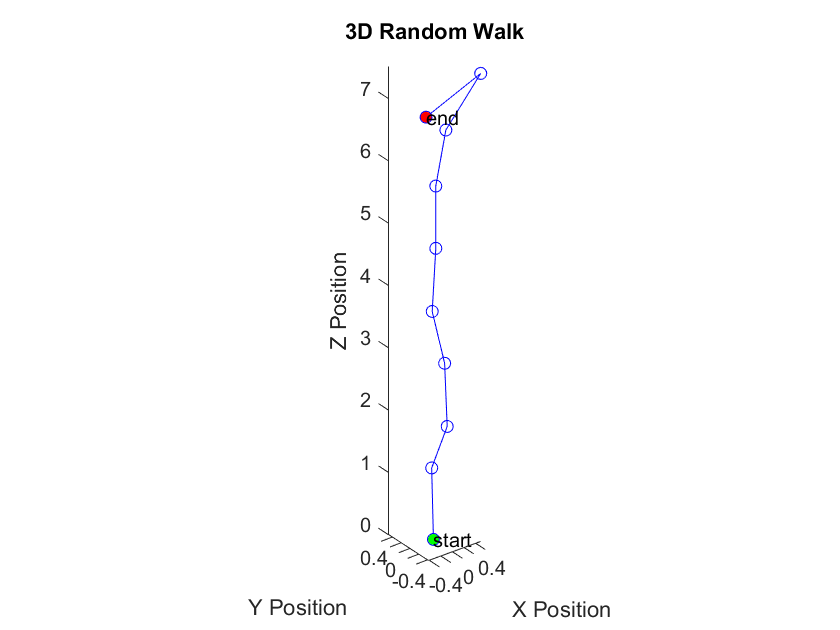

% Creating a plot 
plot3(P(1,:), P(2,:), P(3,:), 'bo-');
title('3D Random Walk');
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');

% Keep the tick sizes the same 
axis equal; 

% Mark the first point in red.
hold on;
plot3(P(1,1), P(2,1), P(3,1), 'go',...
    'MarkerFaceColor', 'g',...
    'MarkerSize', 5);
text(P(1,1), P(2,1), P(3,1), 'start');

% Mark the end point in red.
hold on;
plot3(P(1,n), P(2,n), P(3,n), 'ro',...
    'MarkerFaceColor', 'r',...
    'MarkerSize', 5);
text(P(1,n), P(2,n), P(3,n), 'end');